# Port-Hamiltonian systems / phs class

## Port-Hamiltonian systems

### Motivation

The port-Hamiltonian (PH) approach allows energy-based modeling of dynamic systems from different fields of research and development. Its key idea is to model the interconnection of power components separately from the dynamic behavior of each component. Therefore, this approach is particularly suitable for modeling multi-physics networks. PH systems come with a set of useful properties, including passivity, stability, and controller design principles. An introduction to port-Hamiltonian systems is given in [1], [2].

### Linear time-invariant PH systems, Input-State-Output representation

This toolbox restricts itself to linear, time-invariant port-Hamltonian systems. A very basic, yet effective, way of notation is the **Input-State-Output representation**:


$$\dot{x} = (J-R)Qx + Gu \\ y = G^TQx$$



$$x \in \mathbb{R}^n,~u, y \in \mathbb{R}^p,~J, R, Q \in \mathbb{R}^{n\times n},~ G \in \mathbb{R}^{n\times p}$$


with the following structural constraints:

- 
$$J=-J^T$$
 

- 
$$R=R^T\geq 0$$


- 
$$Q=Q^T>0$$
 

### Extension

An extended version of the Input-State-Output representation was introduced by [3]. It includes a descriptor matrix $E$, an additional input/output matrix $P$ and feed-through matrices $S$ and $N$:


$$E\dot{x} = (J-R)Qx + (G-P)u \\ y = (G+P)^TQx + (S + N) u$$



$$x \in \mathbb{R}^n,~u, y \in \mathbb{R}^p,~J,R,E,Q \in \mathbb{R}^{n\times n},~ G,P \in \mathbb{R}^{n\times p}, ~ S,N \in \mathbb{R}^{p\times p}$$


The matrices must satisfy:

- Skew-adjointness:    $Q^TE = E^TQ$, $Q^TJQ = - Q^TJ^TQ$

- Hamiltonian:             $H(x) = \frac{1}{2}x^TQ^TEx \geq h_0 \in \mathbb{R}~\forall x \in \mathbb{R}$

- 
$$W:=\left\lbrack \begin{array}{cc}
Q^T \mathrm{RQ} & Q^T P\\
P^T Q & S
\end{array}\right\rbrack =W^T \ge 0$$
 

- $S = S^T$, $N = -N^T$ 

## phs-class

The toolbox provides the class ***phs*** which takes input matrices $J$, $R$, $Q$, $G$, $E$, $P$, $S$, and $N$, assesses their validity and stores the matrices as properties. It also offers commonly used functions from the *Control System Toolbox. *

help phs

  phs (class) - class and methods for handling port-Hamiltonian systems
 
  Syntax:
    sys = phs(J, R, Q, G)
    sys = phs(J, R, Q, G, E)
    sys = phs(J, R, Q, G, Opts)
    sys = phs(J, R, Q, G, E, Opts)
    sys = phs(J, R, Q, G, E, P, S, N)
    sys = phs(J, R, Q, G, E, P, S, N, Opts)
 
  Description:
        sys = phs(J, R, Q, G) returns a phs-object representing the
        port-Hamiltonian system sys defined by
            dx/dt = (J - R)*Q*x(t) + G*u(t)
                y = G'*Q*x
             H(x) = 0.5*x'*Q*x      (Hamiltonian)
                f = -dx/dt     (flow)
                e = grad_x(H)  (effort)        [1,2]
 
        sys = phs(J, R, Q, G, E) returns a phs-object representing the
        port-Hamiltonian system sys defined by
            E*dx/dt = (J - R)*Q*x(t) + G*u(t)
                  y = G'*Q*x
               H(x) = 0.5*x'*E'*Q*x   (Hamiltonian)
                  f = -dx/dt     (fl

### phs objects

*phs *objects can be created from the matrices above. During creation, the matrices will be checked with respect to the properties listed in the section above. Mandatory inputs are $J$, $R$, $Q$ and $G$ while $E$, $P$, $S$, and $N$ may be provided if necessary. Additionally, options can be passed as a struct.

**Note:** *phs *objects are **value** **objects** (not handle objects). See [here](https://www.mathworks.com/help/matlab/matlab_oop/comparing-handle-and-value-classes.html) for a comparison. In particular, any function (except of setters) will not alter the *phs*-object itself. If you want to apply changes made, you will need to consider the output of that function.

% Example: Uncomment the code below if necessary
% J = [0, -1; 1, 0]; R = [0, 0; 0, 1]; Q = eye(2); B = [1; 0]; E = 2*eye(2);
% sys_example = phs(J,R,Q,B,E);   % system with descriptor matrix E
% sys_example.isImplicit
% sys_example.makeExplicit        % will return a NEW phs object WITHOUT CHANGING sys_example
% sys_example.isImplicit
% sys_example = sys_example.makeExplicit  % will make sys_example explicit
% sys_example.isImplicit

#### Simple phs object

Let us first create a very simple *phs*-object with the minimum of required values: $J$, $R$, $Q$ and $G$:

J = [0, -1; 1, 0]

J =      0    -1
     1     0


R = [0, 0; 0, 1]

R =      0     0
     0     1


Q = eye(2)

Q =      1     0
     0     1


G = [1; 0]

G =      1
     0


sys1 = phs(J, R, Q, G)

sys1 =   phs with properties:

               J: [2×2 double]
               R: [2×2 double]
               Q: [2×2 double]
               G: [2×1 double]
               E: [2×2 double]
               P: [2×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 2
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 1


#### Extended phs object

Next, we will use the extended definition by also using matrices $E$, $P$, $S$, and $N$:

E = 2*eye(2)

E =      2     0
     0     2


P = [0; 1]

P =      0
     1


S = 10

S = 10

N = 0

N = 0

sys2 = phs(J,R,Q,G,E,P,S,N)

sys2 =   phs with properties:

               J: [2×2 double]
               R: [2×2 double]
               Q: [2×2 double]
               G: [2×1 double]
               E: [2×2 double]
               P: [2×1 double]
               S: 10
               N: 0
            Opts: [1×1 struct]
             dim: 2
          isMIMO: 0
      isImplicit: 1
           isDAE: 0
    hasStaircase: 1


#### Options

Options include enabling/disabling input validation

Opts.inputValidation = false    % default: true

Opts = struct with fields:
    inputValidation: 0


setting tolerance

Opts.inputTolerance = 1e-5      % default: 1e-14

Opts = struct with fields:
    inputValidation: 0
     inputTolerance: 1.0000e-05


enabling/disabling outputs and warnings

Opts.verbose = true             % default: true

Opts = struct with fields:
    inputValidation: 0
     inputTolerance: 1.0000e-05
            verbose: 1


sys3 = phs(J,R,Q,G,Opts)

sys3 =   phs with properties:

               J: [2×2 double]
               R: [2×2 double]
               Q: [2×2 double]
               G: [2×1 double]
               E: [2×2 double]
               P: [2×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 2
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 1


**Note: **Disabling input validation may be helpful for large-scale systems which are expected to be port-Hamiltonian anyway. Input validation can require a significant amount of time since it requires an estimation of eigenvalues.

### phs functions

#### Getter, setter, properties

Accessing and changing the system matrices (and the Opts struct) is easy:

sys1.J

ans =    (2,1)        1
   (1,2)       -1


sys1.J = 2*sys2.J; sys1.J

ans =    (2,1)        2
   (1,2)       -2


sys1.Opts

ans = struct with fields:
    inputValidation: 1
            verbose: 1
     inputTolerance: 1.0000e-10


There also exist some additional properties which can be useful from time to time:

sys1.isImplicit   % Descriptor system: E is not identity

ans = logical
   0


sys2.isImplicit

ans = logical
   1


sys1.isDAE          % Differential algebraic PH system: E is singular

ans = logical
   0


sys1.dim            % dimension

ans = 2

sys1.isMIMO

ans = logical
   0


After having changed a *phs* object's properties, you might want to run input validation (i.e. validation that the system is still a port-Hamiltonian system). This is not done automatically since property validation can be costly for large systems. You can check the properties like this:

phs.inputValidation(sys1)   % will throw an error if the system is not PH, returns true (1) otherwise

ans = logical
   1


#### Transformation, Conversion

The *phs* class also includes some functions which allow system transformation:

sys2.isImplicit           % Descriptor system

ans = logical
   1


sys_exp = sys2.makeExplicit % Same system, now explicit

sys_exp =   phs with properties:

               J: [2×2 double]
               R: [2×2 double]
               Q: [2×2 double]
               G: [2×1 double]
               E: [2×2 double]
               P: [2×1 double]
               S: 10
               N: 0
            Opts: [1×1 struct]
             dim: 2
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


sys_exp.isImplicit

ans = logical
   0


For improved compatibility and convencience, any *phs *object can be converted to *ss- *(Control System Toolbox) or *sss*-objects (sss/sssMOR Toolbox):

sys_ss = ss(sys1)

sys_ss =
 
  A = 
       x1  x2
   x1   0  -2
   x2   2  -1
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sys_sss = sss(sys1)   % runs only when sss-toolbox is installed

sys_sss =   (SSS)(SISO)
  2 state variables, 1 inputs, 1 outputs
  Continuous-time state-space model.


Other useful functions include *scaling*, *makeFull*, *makeSparse *(use 'help' for more details).

#### Analysis

Many of the common system analysis functions from the Control System toolbox have wrappers for *phs*-objects implemented as static functions in the *phs-*class. Among others, these functions include: *bode, bodemag, impulse, lsim, norm, pzmap, *and *step*. Their usage is as for *ss*-objects.

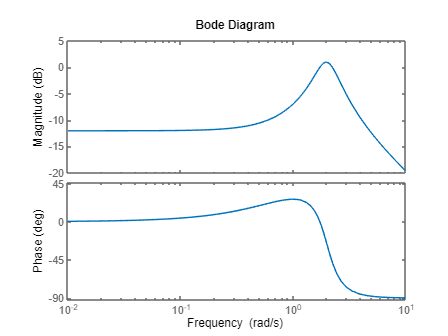

figure(); bode(sys1);

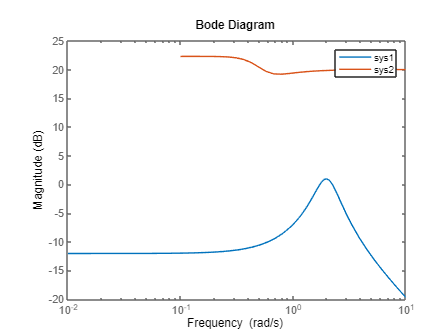

figure(); bodemag(sys1, sys2); legend('sys1','sys2');

norm(sys1)

ans = 0.7906

norm(sys3)

ans = 1.0000

norm(sys1-sys3)

ans = 0.9424

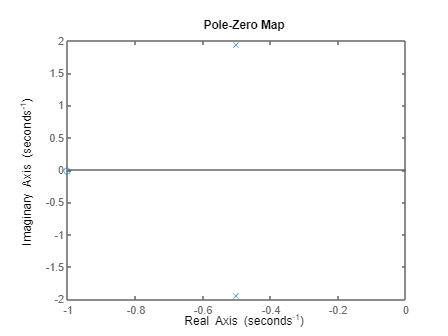

pzmap(sys1)

## References

[1] V. Duindam et al. (2009), *Modeling and Control of Complex Physical Systems*, Book, Springer Berlin Heidelberg.

[2] A. Van der Schaft (2017), $L_2$-Gain and Passivity Techniques in Nonlinear Control, Book, Springer International Publishing.

[3] C. Beattie et al. (2018), *Linear port-Hamiltonian descriptor systems*, Mathematics of Control, Signals, and Systems, 30(4), 2018.

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Julius Durmann    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)